% NumLaneBoundaries gives how many lane boundaries
% 1 and N ones are road edges, 
% can be ignored assuming all lanes are contained
lanes=out.lanes

lanes = struct with fields:
                 Time: [1×1 timeseries]
          IsValidTime: [1×1 timeseries]
          SensorIndex: [1×1 timeseries]
    NumLaneBoundaries: [1×1 timeseries]
       LaneBoundaries: [12×1 struct]


Nlanes=reshape(lanes.NumLaneBoundaries.Data,1,[])'

Nlanes = 2


% laneBoundaries.BoundaryType=
% 0 for no markings (i.e. road edges)
% 1 for solid lines
% 2 for dashed lines
% 5 for double solid lines

lane=out.lanes.LaneBoundaries(1);
lane=reshape(lane,1,[])';
lb=clothoidLaneBoundary;
lb.Curvature=lane.Curvature(1).Data(1);
lb.CurvatureDerivative=lane.CurvatureDerivative(1).Data(1);
lb.CurveLength=lane.CurveLength(1).Data(1);
lb.HeadingAngle=lane.HeadingAngle(1).Data(1);
lb.LateralOffset=lane.LateralOffset(1).Data(1);
lb.BoundaryType=lane.BoundaryType(1).Data(1)

lb =   clothoidLaneBoundary with properties:

              Curvature: -1.1282e-13
    CurvatureDerivative: 1.0595e-14
            CurveLength: 24.0000
           HeadingAngle: 0.2466
          LateralOffset: 2.1500
           BoundaryType: Dashed
               Strength: 0
                XExtent: [0 Inf]
                  Width: 0


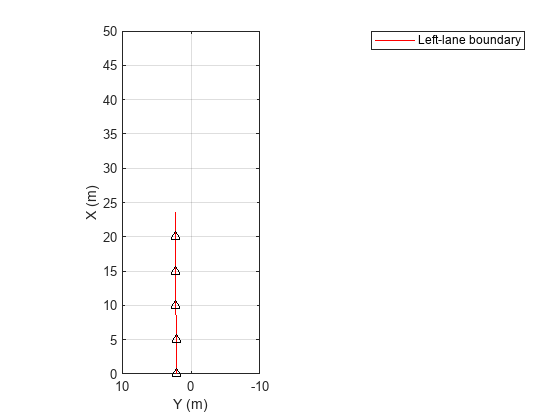

x = linspace(0,50,11);

bep = birdsEyePlot('XLimits',[0 50],'YLimits',[-10 10]);
lbPlotter = laneBoundaryPlotter(bep,'DisplayName','Left-lane boundary','Color','r');
plotLaneBoundary(lbPlotter,lb)
grid on
hold on

laneCoord=out.laneSegmentsCoords.Data(:,1);
plot(x,laneCoord,'k^')


% yl = computeBoundaryModel(lb,x);
% plot(x,yl,'bo')

% [coords, types] = clothoidLaneBoundary2Coords(x,lb);
% plot(x,coords,'k^')